## Set paths

rootdir = '/Users/nbertelsen/projects/cmi_eeg_rs_H';
datadir = fullfile(rootdir, "data");
plotdir = fullfile(rootdir, "plots/reval/global/");
resultsdir = fullfile(rootdir, "results/reval/global/");
eeglabdir = '/Users/nbertelsen/Documents/MATLAB/eeglab_20201226'; 

## Initiate eeglab

cd(eeglabdir), eeglab('nogui'); cd(rootdir)

eeglab: options file is ~/eeg_options.m
EEGLAB: adding "Adjust" v1.1.1 (see >> help eegplugin_adjust)
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Cleanline" v1.04 (see >> help eegplugin_cleanline)
EEGLAB: adding "EEGBrowser" v? (see >> help eegplugin_EEGBrowser)
EEGLAB: adding "FASTER1.2.3b" v? (see >> help eegplugin_FASTER)
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v? (see >> help eegplugin_iclabel)
EEGLAB: adding "IC_MARC-main" v? (see >> help eegplugin_icmarc)
EEGLAB: adding "MFFMatlabIO" v3.6 (see >> help eegplugin_mffmatlabio)
EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline)
EEGLAB: adding "Viewprops" v1.5.4 (see >> help eegplugin_viewprops)
EEGLAB: adding "bva-io" v1.7 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.3 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v? (see >> help eegplu

## Load  datasets

fn_H = 'tidy_adjH_revalsubgroups_global.csv';
dt_H = readtable(fullfile(datadir, 'tidy', fn_H));

fn_stats_rseo = '04_adjH_rsopen_electrodes_subtype*age.csv';
fn_stats_rsec = '04_adjH_rsclosed_electrodes_subtype*age.csv';

dt_stats_rseo = readtable(fullfile(resultsdir, fn_stats_rseo));
dt_stats_rsec = readtable(fullfile(resultsdir, fn_stats_rsec));

## Set parameters

electrodes = unique(dt_H.electrode);
n_channels = size(electrodes, 1);

## Load electrode structure for topoplotting and match electrode names

load(fullfile(rootdir, 'code', 'chanlocs_struct.mat'));
chanlocs_struct(93).labels = 'Cz'; % rename channel '129' in chainlock 'Cz' for congruence with our channel names
if sum(ismember({chanlocs_struct.labels}', electrodes)) == 93
electrodes = {chanlocs_struct.labels}';
else
    disp('Electrode name mismatch!')
    return
end

**Remove unwanted diagnoses and split based on task**

col2keep = {'subid', 'age', 'sex', 'dx', ...
    'rsopen_subgroup_glob', 'rsclosed_subgroup_glob', ...
    'task', 'condition', 'block', ...
    'electrode', 'H'};

dt_H = unique(dt_H(:, col2keep));

dt_rsopen = dt_H(strcmp(dt_H.condition, 'open'), :);
dt_rsclosed = dt_H(strcmp(dt_H.condition, 'closed'), :);

**Get mean H values for resting state eyes open**

td_rsopen = dt_rsopen(strcmp(dt_rsopen.dx, 'TD'), :);
a1_rsopen = dt_rsopen(dt_rsopen.rsopen_subgroup_glob == 1, :);
a2_rsopen = dt_rsopen(dt_rsopen.rsopen_subgroup_glob == 2, :);

td_rsopen_sum = grpstats(td_rsopen,"electrode", "mean", "DataVars","H");
a1_rsopen_sum = grpstats(a1_rsopen,"electrode", "mean", "DataVars","H");
a2_rsopen_sum = grpstats(a2_rsopen,"electrode", "mean", "DataVars","H");

[~, td_rsopen_index] = ismember(electrodes, td_rsopen_sum.electrode); 
[~, a1_rsopen_index] = ismember(electrodes, a1_rsopen_sum.electrode); 
[~, a2_rsopen_index] = ismember(electrodes, a2_rsopen_sum.electrode); 

td_rsopen_2plot = td_rsopen_sum(td_rsopen_index, :);
a1_rsopen_2plot = a1_rsopen_sum(a1_rsopen_index, :);
a2_rsopen_2plot = a2_rsopen_sum(a2_rsopen_index, :);

**Get mean H values for resting state eyes closed**

td_rsclosed = dt_rsclosed(strcmp(dt_rsclosed.dx, 'TD'), :);
a1_rsclosed = dt_rsclosed(dt_rsclosed.rsclosed_subgroup_glob == 1, :);
a2_rsclosed = dt_rsclosed(dt_rsclosed.rsclosed_subgroup_glob == 2, :);

td_rsclosed_sum = grpstats(td_rsclosed,"electrode", "mean", "DataVars","H");
a1_rsclosed_sum = grpstats(a1_rsclosed,"electrode", "mean", "DataVars","H");
a2_rsclosed_sum = grpstats(a2_rsclosed,"electrode", "mean", "DataVars","H");

[~, td_rsclosed_index] = ismember(electrodes, td_rsclosed_sum.electrode); 
[~, a1_rsclosed_index] = ismember(electrodes, a1_rsclosed_sum.electrode); 
[~, a2_rsclosed_index] = ismember(electrodes, a2_rsclosed_sum.electrode); 

td_rsclosed_2plot = td_rsclosed_sum(td_rsclosed_index, :);
a1_rsclosed_2plot = a1_rsclosed_sum(a1_rsclosed_index, :);
a2_rsclosed_2plot = a2_rsclosed_sum(a2_rsclosed_index, :);

## Plotting parameters

% create colorbar
colors2use = {'#ffffd9', '#edf8b1', '#c7e9b4', '#7fcdbb', '#41b6c4', '#1d91c0', '#225ea8', '#253494', '#081d58'};
mycolormap = customcolormap( [0, .125, .25, .375, .5, .625, .75, .875, 1],...
    colors2use);

% set constants
t_sz = 24;
cb_range = [1.2, 1.3, 1.4, 1.5, 1.6, 1.7];
cb_lim = [1.2, 1.7];
cb_t_sz = 20;
cb_tick_sz = 18;
cb_pos = [0.8491 0.2 .06 .6];

**Plot resting state eyes open**

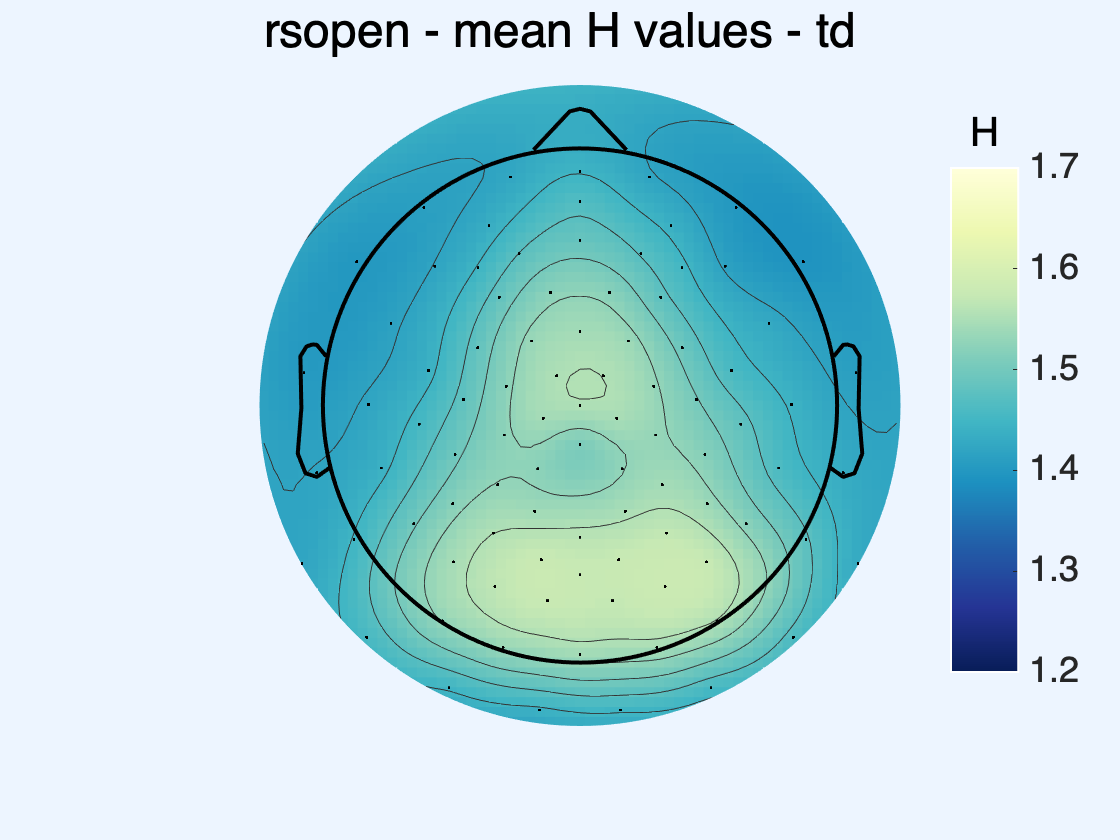

% TD
% open figure and create topoplot
f1 = figure();
f1 = topoplot(td_rsopen_2plot.mean_H, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap);
% set parameters
cb = colorbar; clim(cb_lim); %1.40-1.59
set(cb,'YTick',cb_range); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','H', 'FontSize', cb_t_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t_rsopen_td = sgtitle('rsopen - mean H values - td', 'Color', 'Black'); t_rsopen_td.FontSize = t_sz;
% save
saveas(f1, fullfile(plotdir, 'rsopen/topoplots', '05_adjH_topoplot_mean_H_td.jpg'))

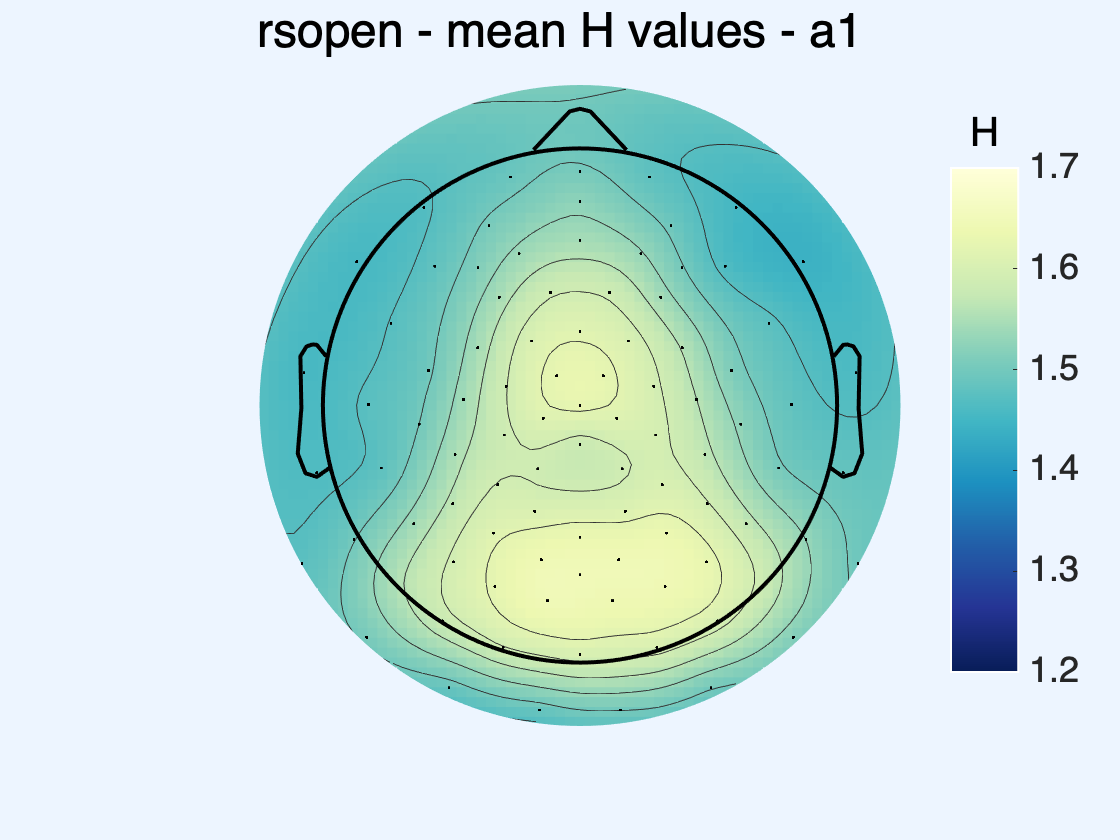


% A1
% open figure and create topoplot
f2 = figure();
f2 = topoplot(a1_rsopen_2plot.mean_H, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %1.45-1.66
% set parameters
cb = colorbar; clim(cb_lim); 
set(cb,'YTick',cb_range); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','H', 'FontSize', cb_t_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t_rsopen_a1 = sgtitle('rsopen - mean H values - a1', 'Color', 'Black'); t_rsopen_a1.FontSize = t_sz;
% save
saveas(f2, fullfile(plotdir, 'rsopen/topoplots', '05_adjH_topoplot_mean_H_a1.jpg'))

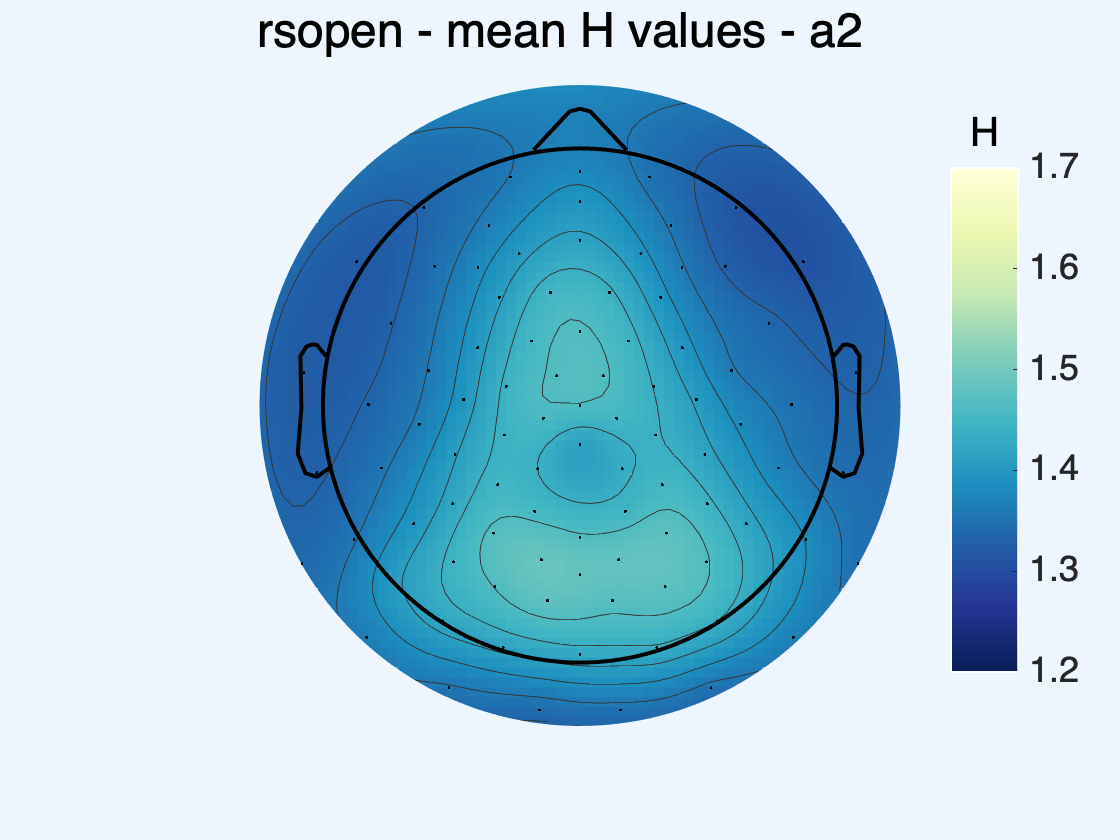


% A2
% open figure and create topoplot
f3 = figure();
f3 = topoplot(a2_rsopen_2plot.mean_H, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %1.31-1.49
% set parameters
cb = colorbar; clim(cb_lim); 
set(cb,'YTick',cb_range); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','H', 'FontSize', cb_t_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t_rsopen_a2 = sgtitle('rsopen - mean H values - a2', 'Color', 'Black'); t_rsopen_a2.FontSize = t_sz;
% save
saveas(f3, fullfile(plotdir, 'rsopen/topoplots', '05_adjH_topoplot_mean_H_a2.jpg'))

## Plot resting state eyes closed 4 colors

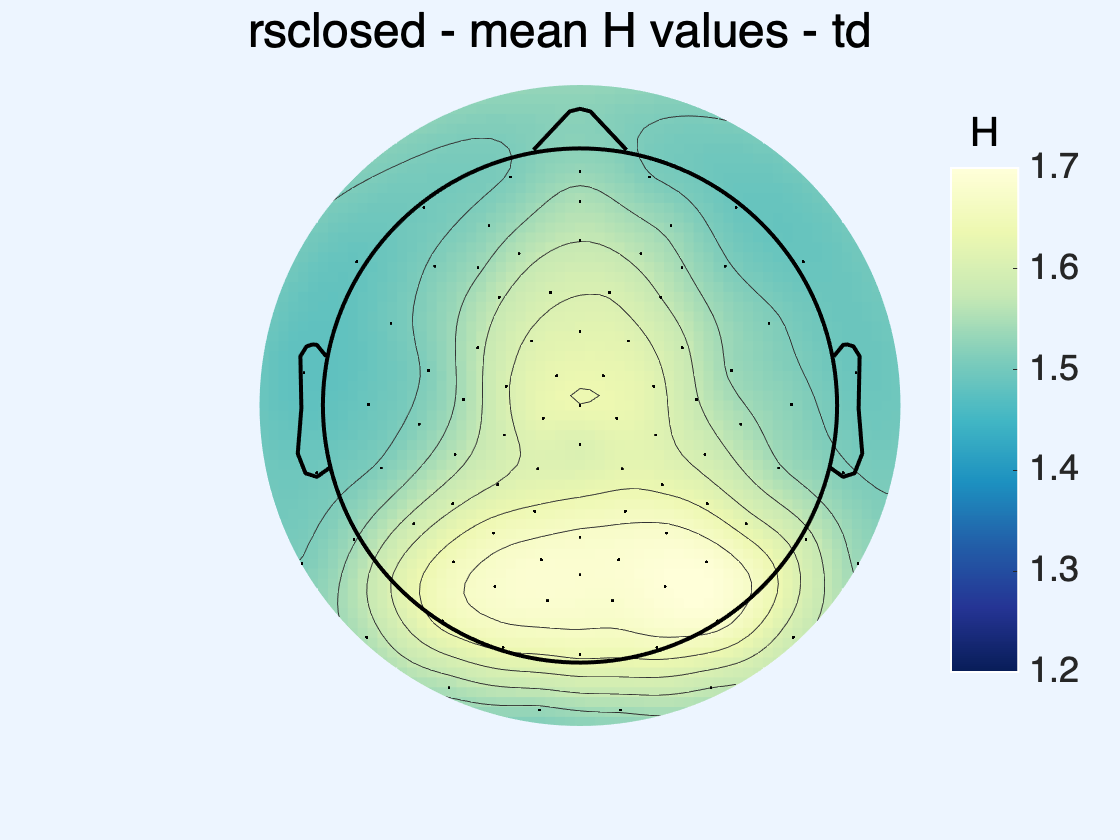

% TD
% open figure and create topoplot
f4 = figure();
f4 = topoplot(td_rsclosed_2plot.mean_H, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %1.47-1.70
% set parameters
cb = colorbar; clim(cb_lim); 
set(cb,'YTick',cb_range); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','H', 'FontSize', cb_t_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t_rsclosed_td = sgtitle('rsclosed - mean H values - td', 'Color', 'Black'); t_rsclosed_td.FontSize = t_sz;
% save
saveas(f4, fullfile(plotdir, 'rsclosed/topoplots', '05_adjH_topoplot_mean_H_td.jpg'))

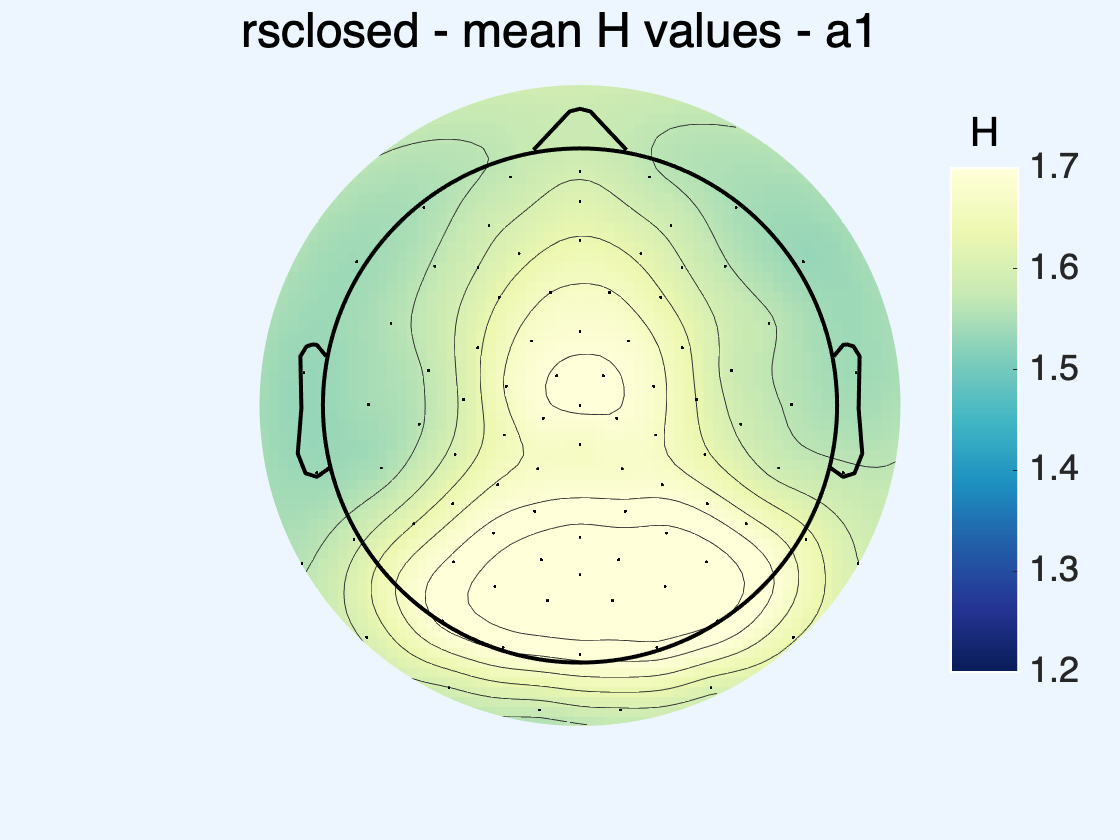


% A1
% open figure and create topoplot
f5 = figure();
f5 = topoplot(a1_rsclosed_2plot.mean_H, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %1.5-1.8
% set parameters
cb = colorbar; clim(cb_lim); 
set(cb,'YTick',cb_range); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','H', 'FontSize', cb_t_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t_rsclosed_a1 = sgtitle('rsclosed - mean H values - a1', 'Color', 'Black'); t_rsclosed_a1.FontSize = t_sz;
% save
saveas(f5, fullfile(plotdir, 'rsclosed/topoplots', '05_adjH_topoplot_mean_H_a1.jpg'))

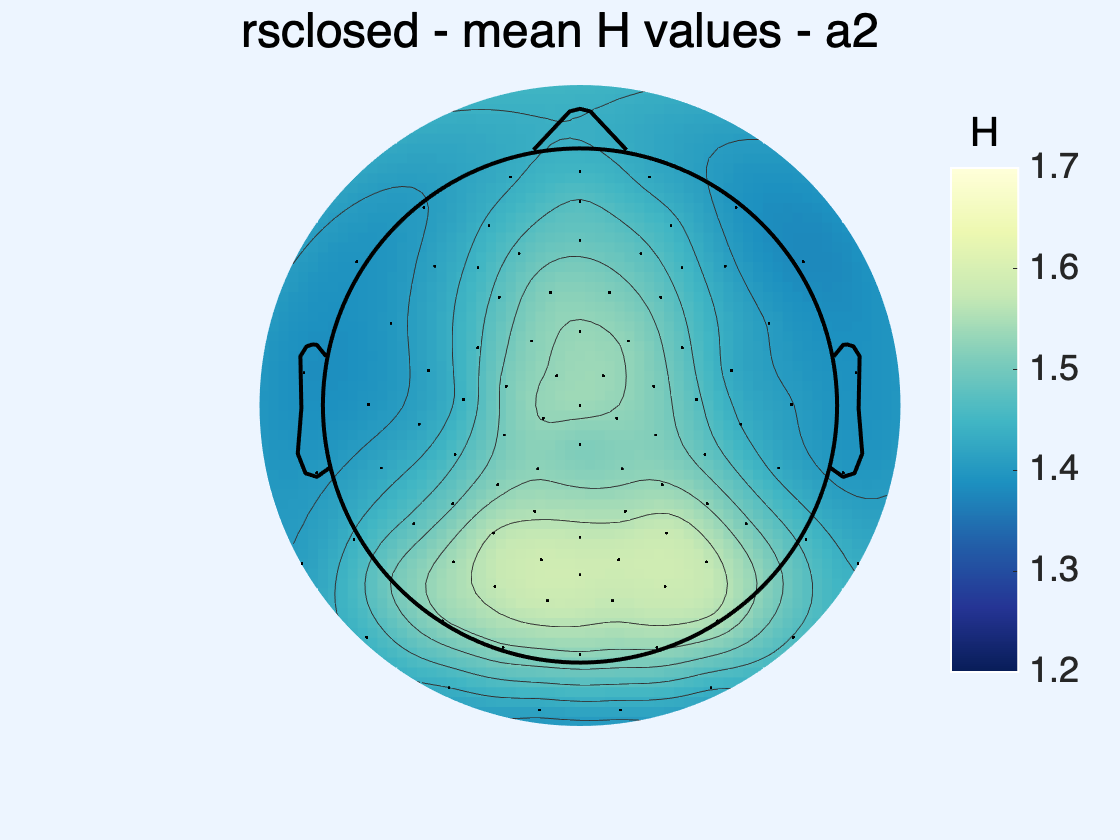


% A2
% open figure and create topoplot
f6 = figure();
f6 = topoplot(a2_rsclosed_2plot.mean_H, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap);
% set parameters
cb = colorbar; clim(cb_lim); 
set(cb,'YTick',cb_range); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','H', 'FontSize', cb_t_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t_rsclosed_a2 = sgtitle('rsclosed - mean H values - a2', 'Color', 'Black'); t_rsclosed_a2.FontSize = t_sz;
% save
saveas(f6, fullfile(plotdir, 'rsclosed/topoplots', '05_adjH_topoplot_mean_H_a2.jpg'))

## Differences plot

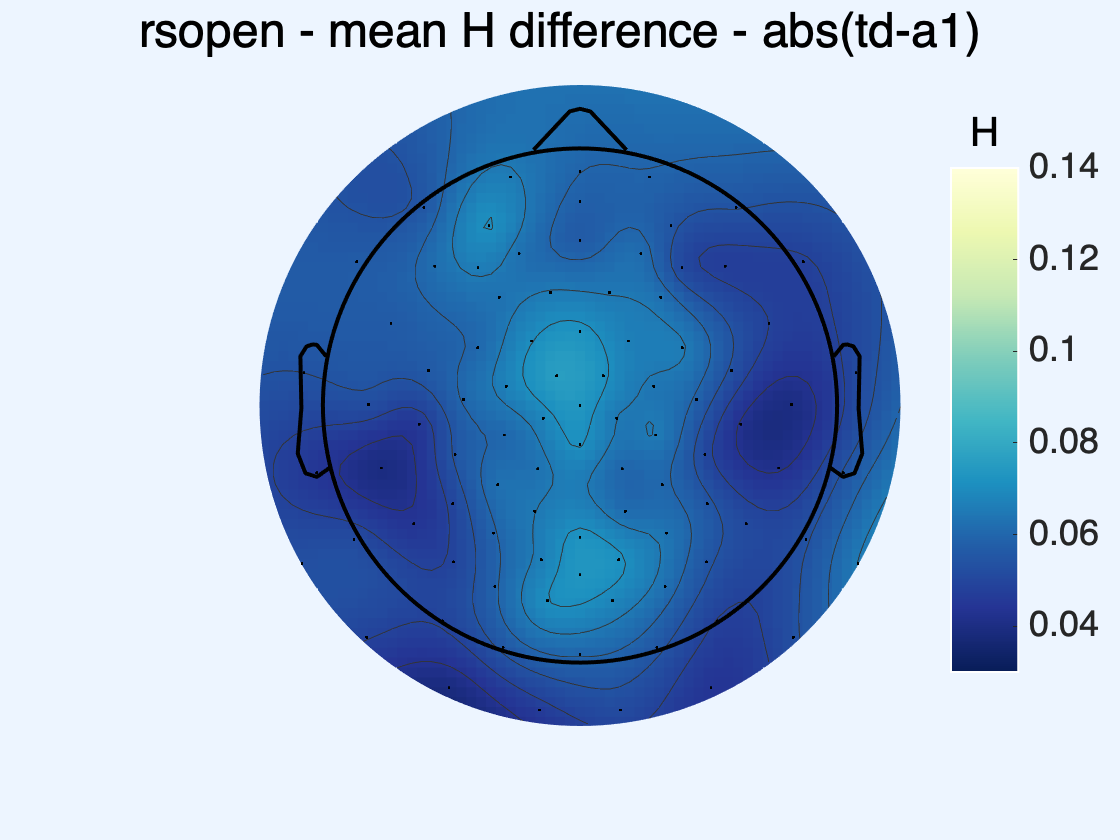

rsopen_tda1_diff = abs(td_rsopen_2plot.mean_H - a1_rsopen_2plot.mean_H);
rsopen_tda2_diff = abs(td_rsopen_2plot.mean_H - a2_rsopen_2plot.mean_H);
rsclosed_tda1_diff = abs(td_rsclosed_2plot.mean_H - a1_rsclosed_2plot.mean_H);
rsclosed_tda2_diff = abs(td_rsclosed_2plot.mean_H - a2_rsclosed_2plot.mean_H);

f7 = figure();
f7 = topoplot(rsopen_tda1_diff, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap);
% set parameters
cb = colorbar; clim([.03, .14]); 
%set(cb,'YTick', 0:.05:.2); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','H', 'FontSize', cb_t_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t_rsopen_tdva2 = sgtitle('rsopen - mean H difference - abs(td-a1)', 'Color', 'Black'); t_rsopen_tdva2.FontSize = t_sz;
saveas(f7, fullfile(plotdir, 'rsopen/topoplots', '05_adjH_topoplot_mean_H_abs_diff_td-a1.jpg'))

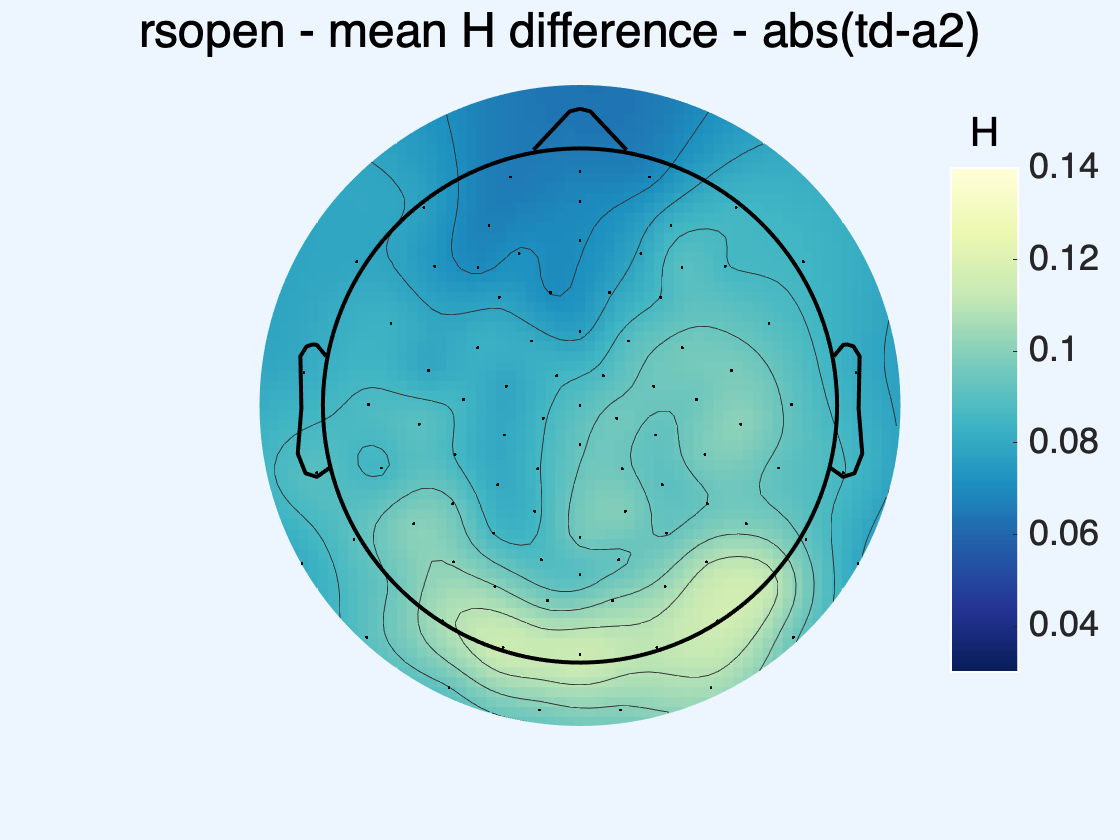


f8 = figure();
f8 = topoplot(rsopen_tda2_diff, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap);
% set parameters
cb = colorbar; clim([.03, .14]); 
%set(cb,'YTick',cb_range); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','H', 'FontSize', cb_t_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t_rsopen_tdva2 = sgtitle('rsopen - mean H difference - abs(td-a2)', 'Color', 'Black'); t_rsopen_tdva2.FontSize = t_sz;
saveas(f8, fullfile(plotdir, 'rsopen/topoplots', '05_adjH_topoplot_mean_H_abs_diff_td-a2.jpg'))

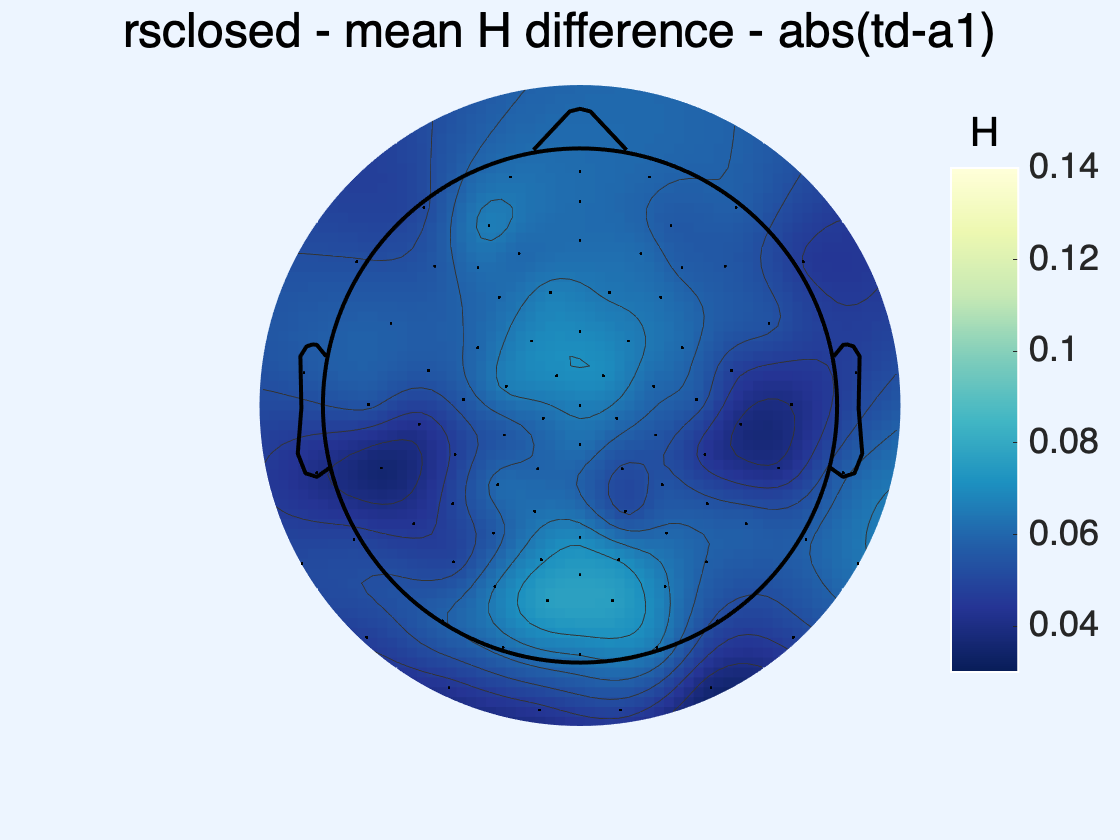


f9 = figure();
f9 = topoplot(rsclosed_tda1_diff, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap);
% set parameters
cb = colorbar; clim([.03, .14]); 
%set(cb,'YTick',cb_range); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','H', 'FontSize', cb_t_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t_rsclosed_tdva1 = sgtitle('rsclosed - mean H difference - abs(td-a1)', 'Color', 'Black'); t_rsclosed_tdva1.FontSize = t_sz;
saveas(f9, fullfile(plotdir, 'rsclosed/topoplots', '05_adjH_topoplot_mean_H_abs_diff_td-a1.jpg'))

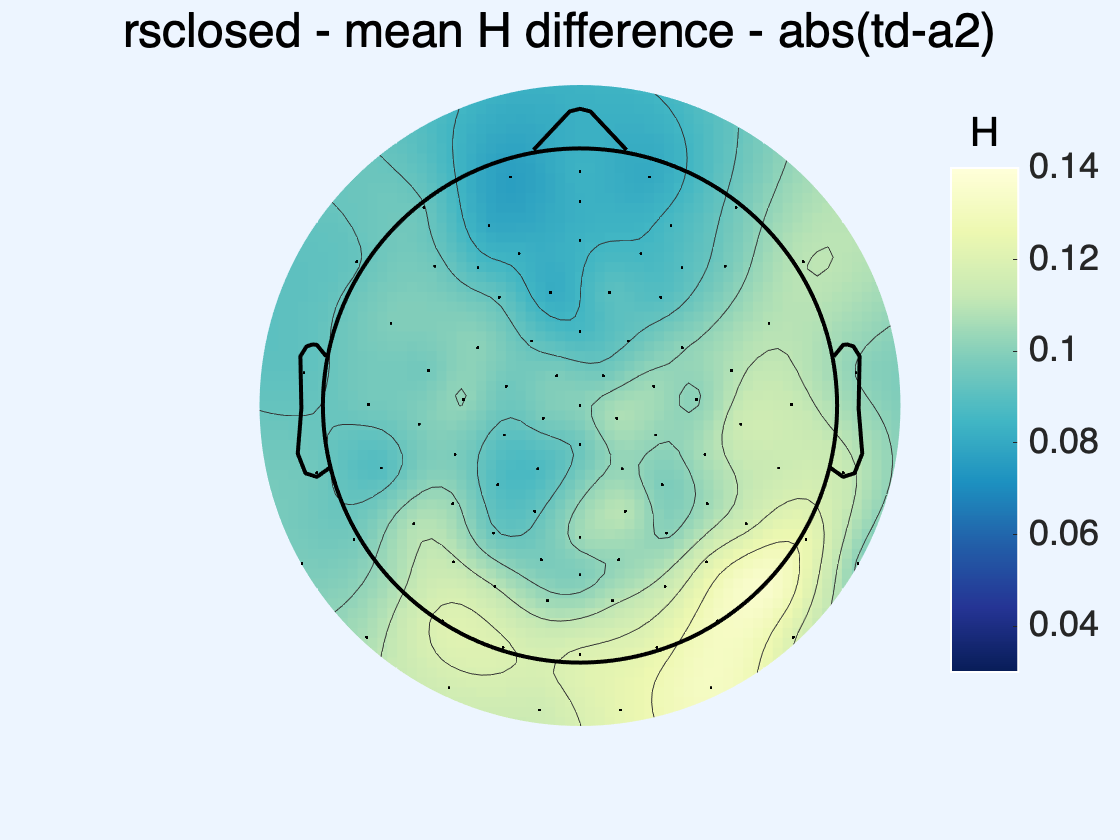


f10 = figure();
f10 = topoplot(rsclosed_tda2_diff, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap);
% set parameters
cb = colorbar; clim([.03, .14]); 
%set(cb,'YTick',cb_range); 
set(cb,'FontSize', cb_tick_sz);
set(cb,'position', cb_pos);
set(get(cb,'title'),'string','H', 'FontSize', cb_t_sz);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t = sgtitle('rsclosed - mean H difference - abs(td-a2)', 'Color', 'Black'); t.FontSize = t_sz;
saveas(f10, fullfile(plotdir, 'rsclosed/topoplots', '05_adjH_topoplot_mean_H_abs_diff_td-a2.jpg'))

**RSOPEN - topoplots of F stats and p-vals**

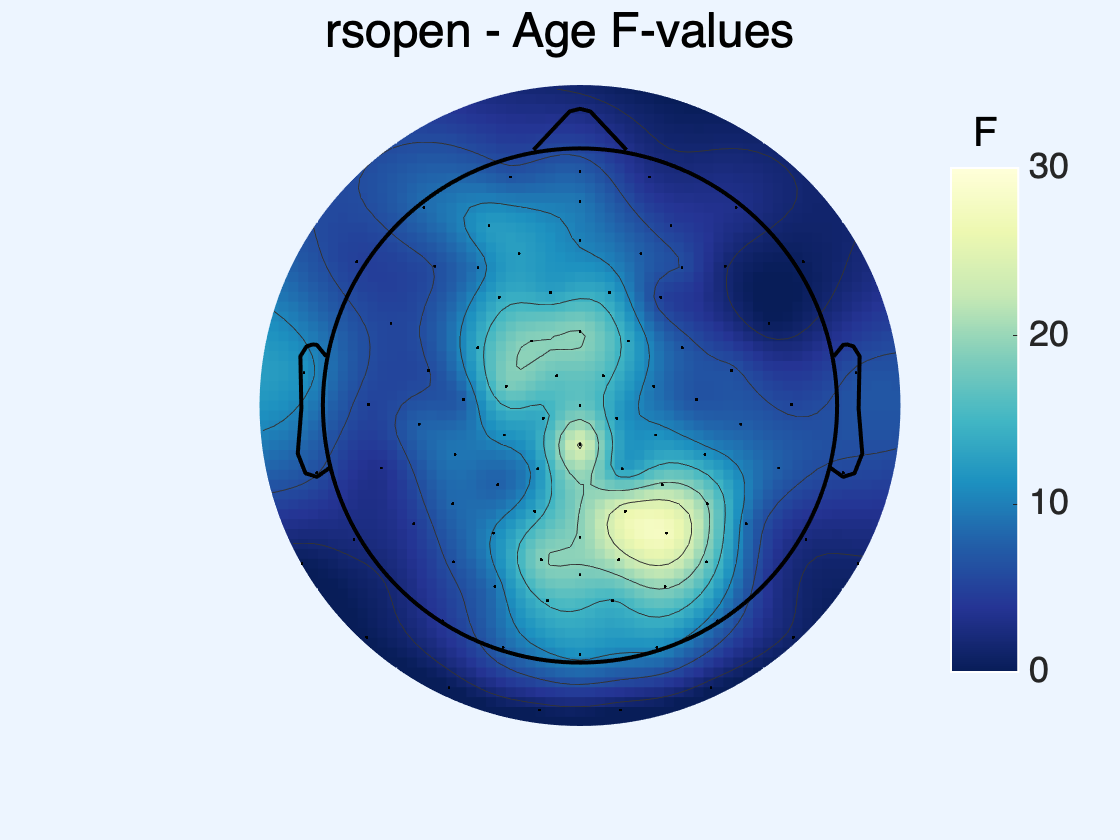

f11 = figure();
topoplot(dt_stats_rseo.age_F, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %0-28
cb = colorbar; clim([0 30]); 
set(cb,'YTick', [0 10 20 30]); 
set(cb,'FontSize', cb_tick_sz); 
set(get(cb,'title'),'string','F', 'FontSize', cb_t_sz);
set(cb,'position',[0.8491 0.2 .06 .6]);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t = sgtitle('rsopen - Age F-values', 'Color', 'Black'); t.FontSize = t_sz;
saveas(f11, fullfile(plotdir, 'rsopen/topoplots', '05_adjH_topoplot_lme_age_F.jpg'))

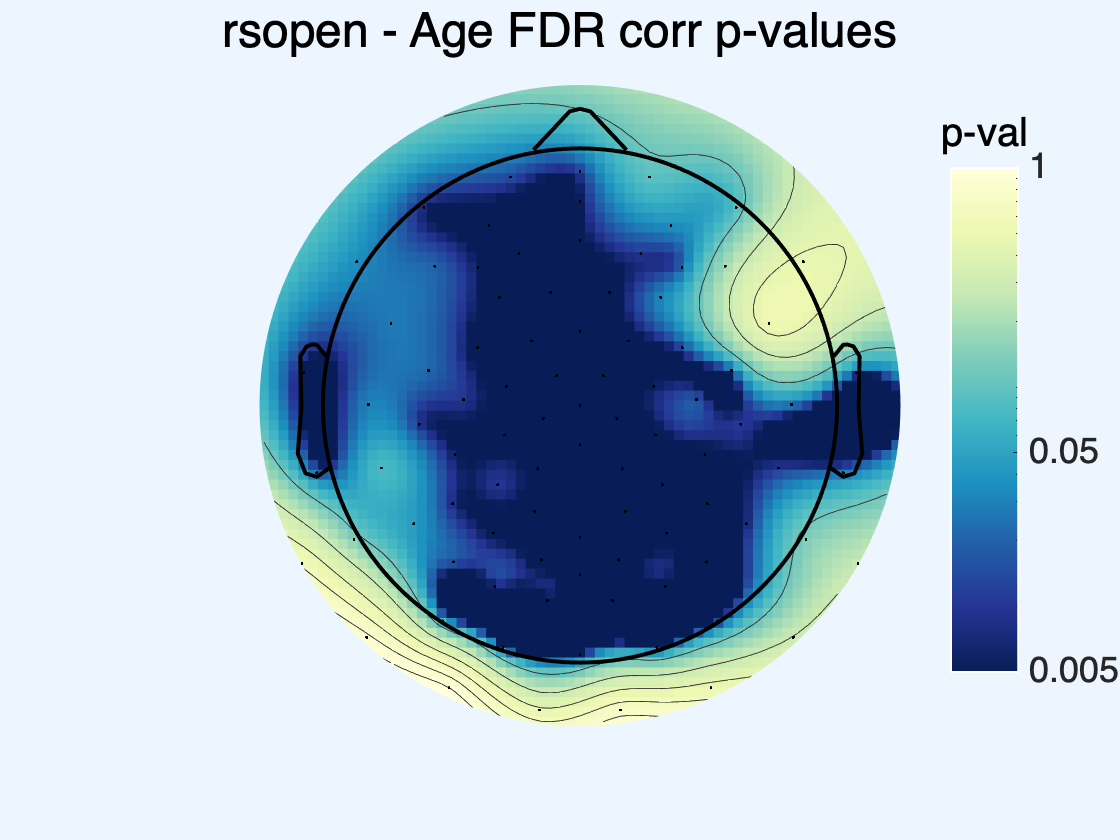


f12 = figure();
% topoplot
topoplot(dt_stats_rseo.age_fdr, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %0-.9
cb = colorbar; 
clim([.005 1]); 
set(cb,'YTick', [.005 .05 1]); 
set(gca,'ColorScale','log')
set(cb,'FontSize', cb_tick_sz); 
set(get(cb,'title'),'string','p-val', 'FontSize', cb_t_sz);
set(cb,'position',[0.8491 0.2 .06 .6]);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t = sgtitle('rsopen - Age FDR corr p-values', 'Color', 'Black'); t.FontSize = t_sz;
saveas(f12, fullfile(plotdir, 'rsopen/topoplots', '05_adjH_topoplot_lme_age_pval_fdr.jpg'))

## RSCLOSED

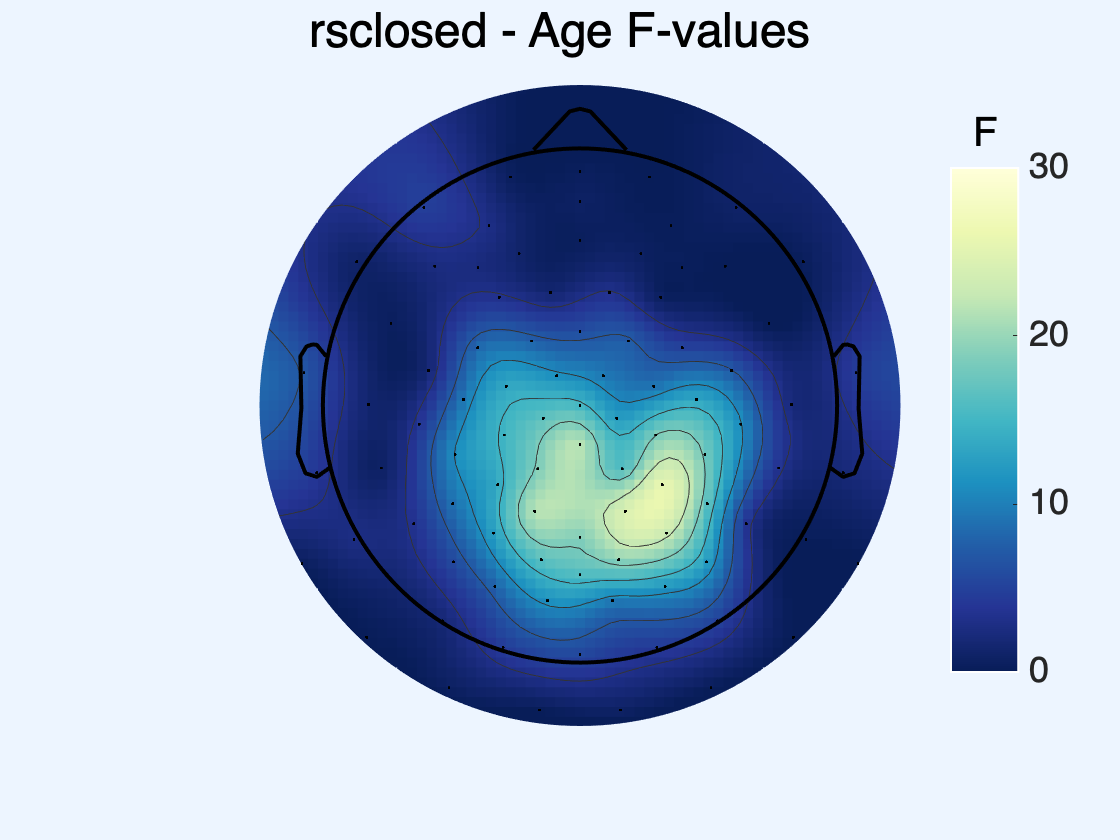

f13 = figure();
% topoplot
topoplot(dt_stats_rsec.age_F, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %0-26
cb = colorbar; clim([0 30]); 
set(cb,'YTick', [0 10 20 30]); 
set(cb,'FontSize', cb_tick_sz); 
set(get(cb,'title'),'string','F', 'FontSize', cb_t_sz);
set(cb,'position',[0.8491 0.2 .06 .6]);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t = sgtitle('rsclosed - Age F-values', 'Color', 'Black'); t.FontSize = t_sz;
saveas(f13, fullfile(plotdir, 'rsclosed/topoplots', '05_adjH_topoplot_lme_age_F.jpg'))

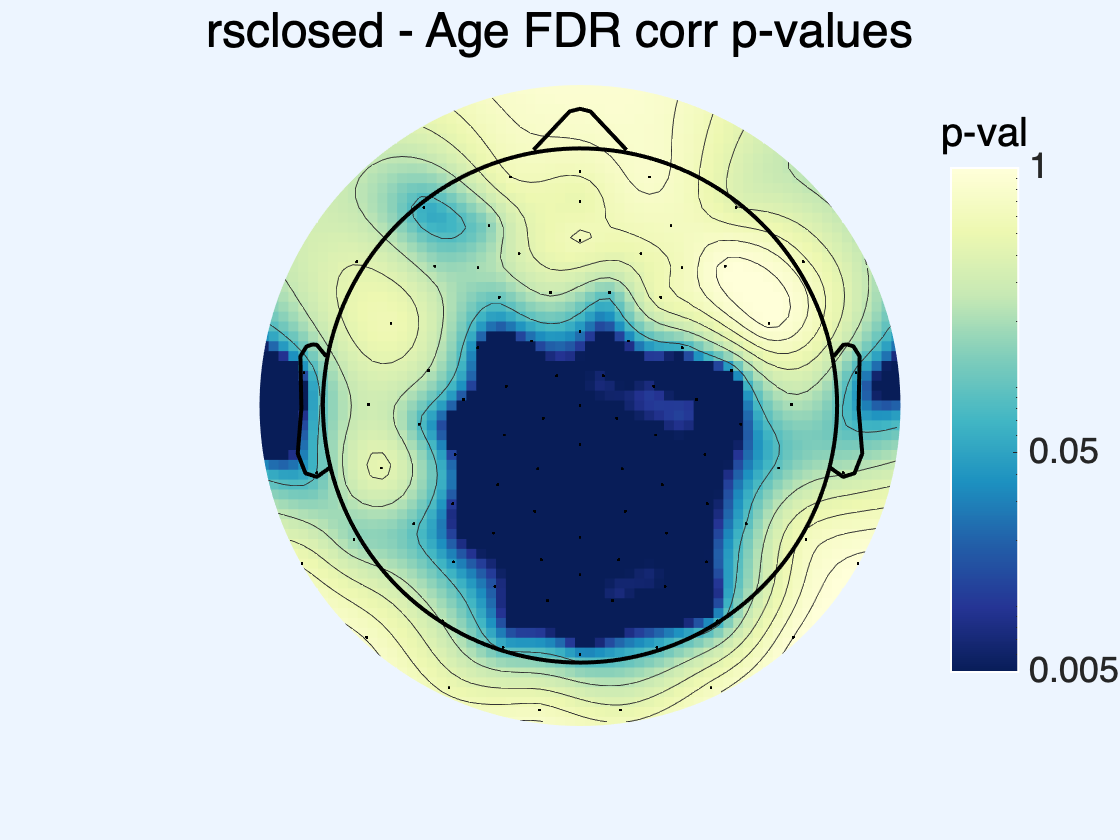


f14 = figure();
% topoplot
topoplot(dt_stats_rsec.age_fdr, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %0-1
cb = colorbar; 
clim([.005 1]); 
set(cb,'YTick', [.005 .05 1]); 
set(gca,'ColorScale','log')
set(cb,'FontSize', cb_tick_sz); 
set(get(cb,'title'),'string','p-val', 'FontSize', cb_t_sz);
set(cb,'position',[0.8491 0.2 .06 .6]);
annotation('rectangle',cb.Position,'Color','w','FaceColor','none','LineWidth',1);
t = sgtitle('rsclosed - Age FDR corr p-values', 'Color', 'Black'); t.FontSize = t_sz;
saveas(f14, fullfile(plotdir, 'rsclosed/topoplots', '05_adjH_topoplot_lme_age_pval_fdr.jpg'))